# Linear Control Design II - Group Work Problem Module 3

## Description

This exercise is based on the work carried out in the Group Work Problem Module 2. For the electro-mechanical system illustrated in Figure 1 and described in Group Work Problem Module 2 the goals for this assignment is: a) linearize the electromagnetic force resulted from the change in current and change in displacement. I.e. $Ki$ and $Ks$; b) derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


c)  investigate the vibrations of the structure when different initial conditions and inputs are present;

d) compare the obtained results from Group Work Module 2 with the results from this Group Work Module.

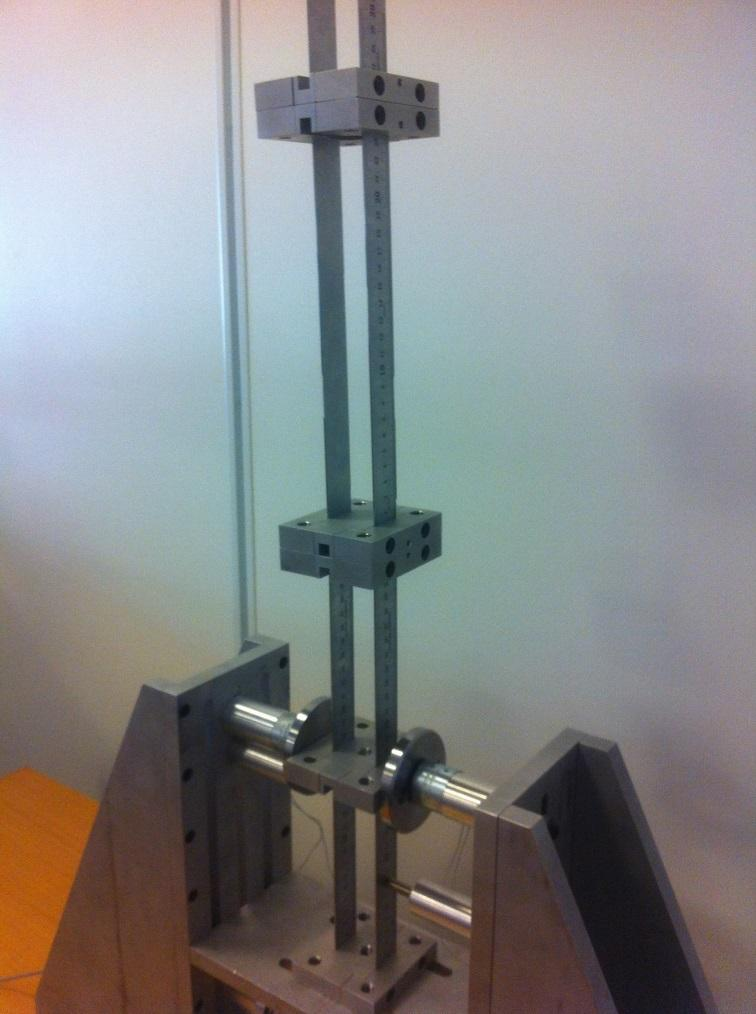


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


The parameters needed for the assignment are given below.

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

l = 24e-3; % mm, small
r = 14e-3 / 2;
A = pi*r^2;
R = 148.2;
L = 800e-3; % [H]
iMax = 0.14; % measured at 24v

gam = 0.5;          % bias ratio - normally chosen between 0.2-0.5
ib = iMax*gam;      % Bias current
mu = 4*pi*1e-7;     % Permeability of free space (vacuum)
x0 = 2e-3;          % displacement operation point

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

**Problem 1**

Linearize the electromagnetic force resulted from the change in current and change in displacement.

Define $Ki$ and $Ks$

% Your solution goes here
% Ki
Ki=mu*N^2*A*ib/x0^2;
% Ks
Ks=mu*N^2*A*(ib^2)/x0^3;

**Problem 2**

Derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


% Your solution goes here:
% Upload a picture or fill in your code 

Ax = [-R/L 0 Ki/L 0 0 0 0; 0 0 1 0 0 0 0; ...
    -Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0; ...
    0 0 0 0 1 0 0; 0 k2/m2  0 -(k2+k3)/m2 0 k3/m2 0; ...
    0 0 0 0 0 0 1; 0 0 0 k3/m3 0 -k3/m3 0]

Ax =       -185.25            0           70            0            0            0            0
            0            0            1            0            0            0            0
      -78.652       -13197            0       5837.2            0            0            0
            0            0            0            0            1            0            0
            0       9710.5            0       -11656            0       1945.6            0
            0            0            0            0            0            0            1
            0            0            0       1945.6            0      -1945.6            0



Bx = [1/L 0 0 0 0 0 0]'

Bx =          1.25
            0
            0
            0
            0
            0
            0


Cx = [ 0 1 0 0 0 0 0]

Cx =      0     1     0     0     0     0     0


Dx = 0;


**Problem 3**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results. 

% Your solution goes here:
u_0 = 0;
x_0 = [ 0 0.001 0 0 0 0 0]';

x0 = 5e-3;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
Ki=mu*N^2*A*ib/x0^2;
Ks=mu*N^2*A*(ib^2)/x0^3;
Ax = [  -R/L 0 Ki/L 0 0 0 0;    0 0 1 0 0 0 0; ...
        -Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0; ...
        0 0 0 0 1 0 0;  0 k2/m2  0 -(k2+k3)/m2 0 k3/m2 0; ...
        0 0 0 0 0 0 1;  0 0 0 k3/m3 0 -k3/m3 0]

Ax =       -185.25            0           28            0            0            0            0
            0            0            1            0            0            0            0
      -31.461       -10885            0       5837.2            0            0            0
            0            0            0            0            1            0            0
            0       9710.5            0       -11656            0       1945.6            0
            0            0            0            0            0            0            1
            0            0            0       1945.6            0      -1945.6            0



sim('electroMagneticModel_SS');
time = i.time;

figure(1)
plot(time, i.signals.values)
xlabel('Time $[s]$')
ylabel('Amplitude $[A]$')
title('Current w/ $s_0 = 5mm$')
figure(2)
plot(time, x1.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

figure(3)
plot(time, x1d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

figure(4)
plot(time, x2.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

figure(5)
plot(time, x2d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

figure(6)
plot(time, x3.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

figure(7)
plot(time, x3d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')


x0 = 3e-3;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
Ki=mu*N^2*A*ib/x0^2;
Ks=mu*N^2*A*(ib^2)/x0^3;
Ax = [  -R/L 0 Ki/L 0 0 0 0;    0 0 1 0 0 0 0; ...
        -Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0; ...
        0 0 0 0 1 0 0;  0 k2/m2  0 -(k2+k3)/m2 0 k3/m2 0; ...
        0 0 0 0 0 0 1;  0 0 0 k3/m3 0 -k3/m3 0]

Ax =       -185.25            0       46.667            0            0            0            0
            0            0            1            0            0            0            0
      -52.434       -11668            0       5837.2            0            0            0
            0            0            0            0            1            0            0
            0       9710.5            0       -11656            0       1945.6            0
            0            0            0            0            0            0            1
            0            0            0       1945.6            0      -1945.6            0


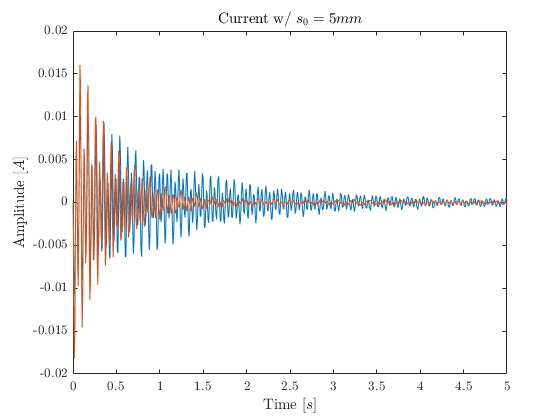

sim('electroMagneticModel_SS');
time = i.time;

figure(1)
hold on
plot(time, i.signals.values)
xlabel('Time $[s]$')
ylabel('Amplitude $[A]$')
title('Current w/ $s_0 = 5mm$')

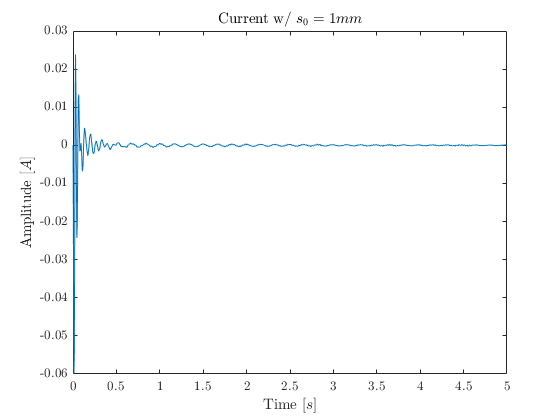


figure(2)
hold on
plot(time, x1.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

figure(3)
hold on
plot(time, x1d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

figure(4)
hold on
plot(time, x2.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

figure(5)
hold on
plot(time, x2d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

figure(6)
hold on
plot(time, x3.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

figure(7)
hold on
plot(time, x3d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

x0 = 1e-3;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
Ki=mu*N^2*A*ib/x0^2;
Ks=mu*N^2*A*(ib^2)/x0^3;
Ax = [  -R/L 0 Ki/L 0 0 0 0;    0 0 1 0 0 0 0; ...
        -Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0; ...
        0 0 0 0 1 0 0;  0 k2/m2  0 -(k2+k3)/m2 0 k3/m2 0; ...
        0 0 0 0 0 0 1;  0 0 0 k3/m3 0 -k3/m3 0];
sim('electroMagneticModel_SS');
time = i.time;

figure
plot(time, i.signals.values)
xlabel('Time $[s]$')
ylabel('Amplitude $[A]$')
title('Current w/ $s_0 = 1 mm$')

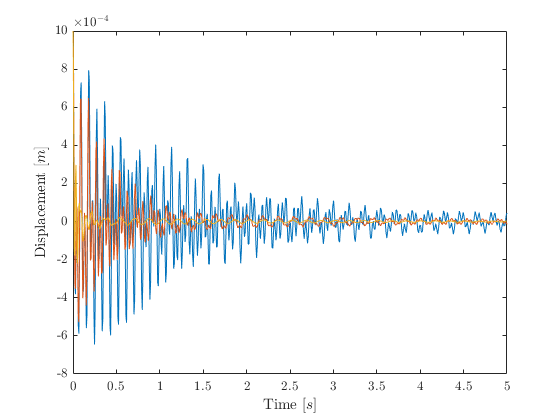


figure(2)
hold on
plot(time, x1.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

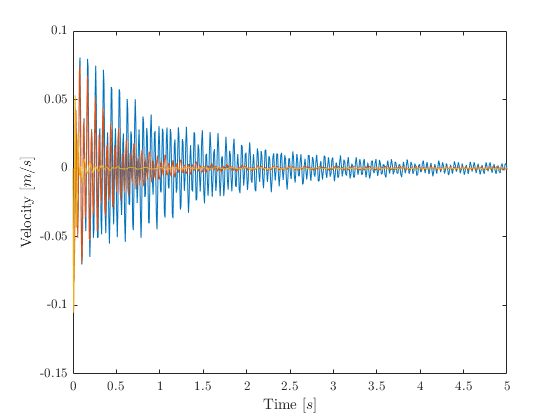


figure(3)
hold on
plot(time, x1d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

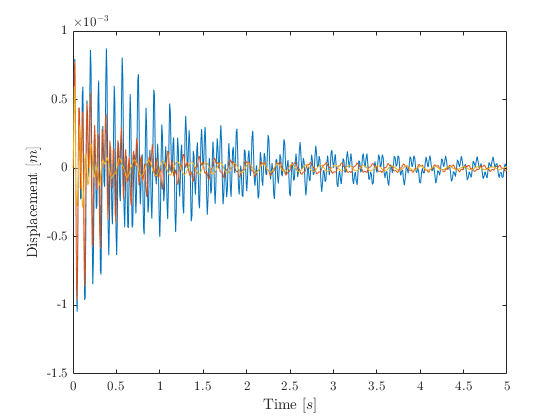


figure(4)
hold on
plot(time, x2.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

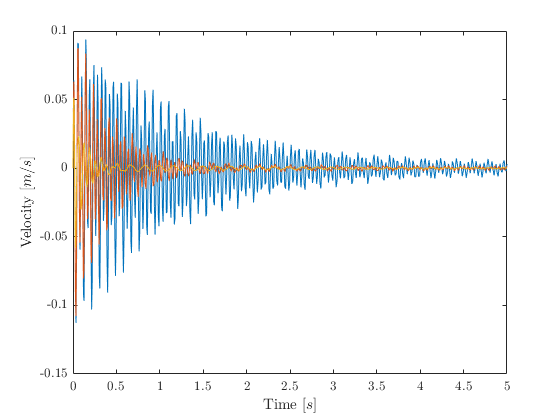


figure(5)
hold on
plot(time, x2d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

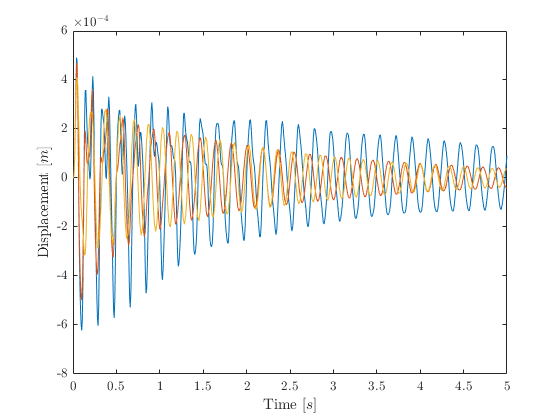


figure(6)
hold on
plot(time, x3.signals.values);
xlabel('Time $[s]$')
ylabel('Displacement $[m]$')

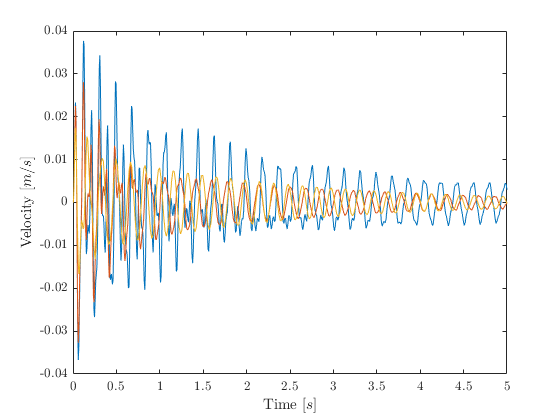


figure(7)
hold on
plot(time, x3d.signals.values);
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')

**Problem 4**

What is the maximum lateral displacement experienced by the three masses when an initial condition of velocity of 5 mm/s acts on mass 3, assuming $s_0$=2 mm?

% Your solution goes here:



**Problem 5**

 A step function $u(t)$=10 V is send to the electromagnets, assuming all initial conditions of lateral displacement, velocity and current nill. How will the three masses vibrate and how will the current change, i.e. amplitudes and frequencies. 

% Your solution goes here:



**Problem 6**

Compare the obtained results from Group Work Module 2 (problems 4, 5 and 6) with the results from this Group Work Module (problems 3, 4 and 5).

% Your solution goes here:

